# EJERCICIOS ENTREGABLES PRÁCTICA 2-3

### Ejercicio 2 (2,75 puntos). Diagramas de bloques.

#### Utilizando los comandos connect y sumblk de MATLAB (véase en Mathworks), construya el diagrama de bloques de la figura para, posteriormente, obtener las funciones de transferencia $\frac{C\left(s\right)}{R\left(s\right)}\;y\;\frac{C\left(s\right)}{D\left(s\right)}$mediante el principio de superposición.

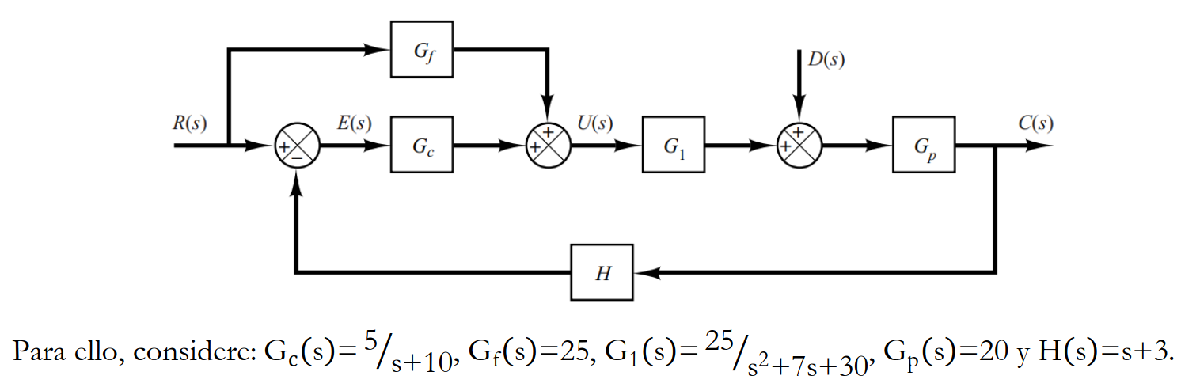

% Definimos las funciones de cada
Gc=tf([5],[1 10])

Gc =
 
    5
  ------
  s + 10
 
Continuous-time transfer function.
Model Properties


Gf=tf(25)

Gf =
 
  25
 
Static gain.
Model Properties


G1=tf([25],[1 7 30])

G1 =
 
        25
  --------------
  s^2 + 7 s + 30
 
Continuous-time transfer function.
Model Properties


Gp=tf(20)

Gp =
 
  20
 
Static gain.
Model Properties


H=tf([1 3],[1])

H =
 
  s + 3
 
Continuous-time transfer function.
Model Properties


Como es un diagrama con varias entradas, lo que tenemos que aplicar es el teorema de superposición para las entradas, de la siguiente manera:

- **PASO 1**: Configuramos todas las entradas a 0 excepto una.

- **PASO 2:** Reducimos el sistema que queda sólo con la entrada que NO hemos puesto a 0

- **PASO 3:** Calculamos la respuesta a esa entrada

- **PASO 4:** Repetimos con las demás entradas

- **PASO 5:** Sumamos todas las salidas obtenidas para obtener la total

Y, para las entradas, simplemente las calculamos por separado, a ver cuánto vale cada una.

Procedemos de la siguiente manera:

***1.SALIDAS D = 0.*** Quedaría el siguiente sistema:

Gc.InputName = "e";  
Gc.OutputName = "uc";

Gf.InputName = "r";  
Gf.OutputName = "uf";

G1.InputName = "u";  
G1.OutputName = "u1";

Gp.InputName = "u1";  
Gp.OutputName = "y";

H.InputName = "y";  
H.OutputName = "yh";

S1 = sumblk("e = r - yh");
S2 = sumblk("u = uc + uf");

T = connect(Gc,G1,Gf,Gp,H,S1,S2,"r","y");
Sis1 = tf(T) % Funcion de transferencia resultante 1

Sis1 =
 
  From input "r" to output "y":
      1.25e04 s + 1.275e05
  ----------------------------
  s^3 + 17 s^2 + 2600 s + 7800
 
Continuous-time transfer function.
Model Properties


***2.SALIDAS R = 0.*** Quedaría el siguiente sistema:

Gc.InputName = "e";  
Gc.OutputName = "u";

G1.InputName = "u";  
G1.OutputName = "u1";

Gp.InputName = "ud";  
Gp.OutputName = "y";

H.InputName = "y";  
H.OutputName = "yh";

S1 = sumblk("e = -yh");
S2 = sumblk("ud = u1 + d");

T = connect(Gc,G1,Gp,H,S1,S2,"d","y");
Sis2 = tf(T)% Funcion de transferencia resultante 2

Sis2 =
 
  From input "d" to output "y":
  20 s^3 + 340 s^2 + 2000 s + 6000
  --------------------------------
    s^3 + 17 s^2 + 2600 s + 7800
 
Continuous-time transfer function.
Model Properties


Luego el resultado final sera la suma de ambas:

SisTotal= Sis1 + Sis2 % El sistema final se puede simplificar al dividir entre s^3 + 17 s^2 + 2600 s + 7800

SisTotal =
 
  From input to output "y":
  20 s^6 + 680 s^5 + 72280 s^4 + 1.42e06 s^3 + 4.262e07 s^2 + 4.602e08 s + 1.041e09
  ---------------------------------------------------------------------------------
    s^6 + 34 s^5 + 5489 s^4 + 1.04e05 s^3 + 7.025e06 s^2 + 4.056e07 s + 6.084e07
 
Continuous-time transfer function.
Model Proper